# Statistical Analysis 

This lecture will cover several of the tools in MATLAB for performing statistical analysis on data sets. 

### Correlation - Two Variables

Helps identify if a linear relationship exists between two variables

Different types of correlation - Pearson's and Spearman (rank)

- Pearson's - measures the strength and direction of a linear relationship between two variables

- Spearman - measures the strength and direction of a monotonic relationship between two variables

Both of these measures of correlation are on a scale of -1 to 1.

Consider the two arrays, *A* and *B*: 

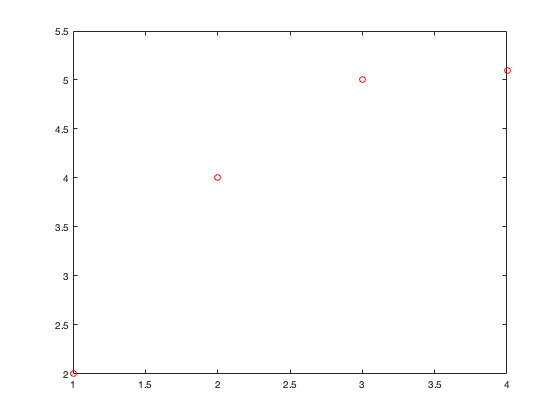

A = [1, 2, 3, 4];
B = [2, 4, 5, 5.1];
plot(A,B,'ro')

Based on the above plot, what values would you guess for the Pearson's and Spearman correlation estimates?

We can quantify the actual correlation using the `corr2` function. The `corr2` function outputs the 2-D correlation coefficient, *r*, for the two arrays.

r = corr2(A,B)

r = 0.9244

As expected, the value for *r *is fairly high because the two variables appear to have a strong linear relationship. 

We can also use the `corr `function, which outputs the pairwise correlation between the columns of two matrices. With the `corr` function, we have the option to specify Pearson or Spearman correlation by using the `'type' `option. Note that we have to transpose the arrays in order to arrange the data into columns.

r = corr(A',B',"type","Pearson")

r = 0.9244


r = corr(A',B',"type","Spearman")

r = 1

The output of the Pearson command is equivalent to the output of the `corr2` command. The output of 1 for the Spearman command makes sense because our two arrays are completely monotonic, meaning that as one variable increases, so does the other. 

Once we have *r, *we can easily calculate the coefficient of determination, $r^2 

$. The coefficient of determination measures the proportion of variance in the dependent variable that can be explained by the independent variable. 

r_squared = r^2

r_squared = 1

### Correlation - Multiple Variables

We can also examine the correlation between multiple variables. Load the Framingham dataset for use in the following examples.

fram = readtable("../frmgham.xls");

Again, if we are only interested in two variables, we can use the `corr2 `command. Find the correlation between systolic and diastolic blood pressure.

sys_bp = fram.SYSBP;
dia_bp = fram.DIABP;
corr2(sys_bp,dia_bp)

ans = 0.7116

If we are interested in more than two variables, we must use the `corr` function, which returns a matrix of the correlation coefficients. 

Find the correlation coefficients for columns 2-11 of the Framingham dataset. First, extract these columns from the full dataset.

fram_2_11 = fram(:,2:11);

What variables are included in these ten columns?

var_names = fram_2_11.Properties.VariableNames

var_names = 1×10 cell array
    {'SEX'}    {'TOTCHOL'}    {'AGE'}    {'SYSBP'}    {'DIABP'}    {'CURSMOKE'}    {'CIGPDAY'}    {'BMI'}    {'DIABETES'}    {'BPMEDS'}


In order for the `corr `function to work correctly, we need to remove the rows containing NaN. For this process, you can use the `rmmissing` command, which removes any rows containing missing data.

fram_noNaN = rmmissing(fram_2_11);

Now that the NaN values have been removed from the matrix, we can find the correlation coefficients.

r = corr(fram_noNaN.Variables)

r =     1.0000    0.1309    0.0267    0.0438   -0.0526   -0.1562   -0.2514   -0.0740   -0.0232    0.0838
    0.1309    1.0000    0.1655    0.1580    0.1360   -0.0483   -0.0372    0.0843    0.0060    0.0612
    0.0267    0.1655    1.0000    0.3832    0.0576   -0.2522   -0.2253    0.0612    0.1323    0.2002
    0.0438    0.1580    0.3832    1.0000    0.7108   -0.1438   -0.1011    0.2707    0.1362    0.3287
   -0.0526    0.1360    0.0576    0.7108    1.0000   -0.0750   -0.0298    0.3340    0.0229    0.2267
   -0.1562   -0.0483   -0.2522   -0.1438   -0.0750    1.0000    0.7806   -0.1648   -0.0429   -0.0896
   -0.2514   -0.0372   -0.2253   -0.1011   -0.0298    0.7806    1.0000   -0.0996   -0.0451   -0.0845
   -0.0740    0.0843    0.0612    0.2707    0.3340   -0.1648   -0.0996    1.0000    0.0889    0.0984
   -0.0232    0.0060    0.1323    0.1362    0.0229   -0.0429   -0.0451    0.0889    1.0000    0.0770
    0.0838    0.0612    0.2002    0.3287    0.2267   -0.0896   -0.0845    0.0984    0.0

Use the `maxk` function to find five highest correlation features (positive or negative) for each variable as well as the index. We will specify for the function to return the five largest values for each column, the indeces of these vaues, and to use absolute values to find the maximums.  

[max_corr, I] = maxk(r,5,"ComparisonMethod","abs")

max_corr =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.2514    0.1655    0.3832    0.7108    0.7108    0.7806    0.7806    0.3340    0.1362    0.3287
   -0.1562    0.1580   -0.2522    0.3832    0.3340   -0.2522   -0.2514    0.2707    0.1323    0.2267
    0.1309    0.1360   -0.2253    0.3287    0.2267   -0.1648   -0.2253   -0.1648    0.0889    0.2002
    0.0838    0.1309    0.2002    0.2707    0.1360   -0.1562   -0.1011   -0.0996    0.0770    0.0984


I =      1     2     3     4     5     6     7     8     9    10
     7     3     4     5     4     7     6     5     4     4
     6     4     6     3     8     3     1     4     3     5
     2     5     7    10    10     8     3     6     8     3
    10     1    10     8     2     1     4     7    10     8


What are some of the variables with the highest correlation? We have to ignore the 1's because those values correspond to the variable's correlation with itself. Aside from the 1's in the correlation coefficient matrix, what are the three highest values and what indeces do they correspond to?

- 0.7806 - Indeces 6 and 7

- 0.7108 - Indeces 4 and 5

- 0.3832 - Indeces 3 and 4

We can then look up the actual variable names with these indeces.

var_names(:,[6,7])

ans = 1×2 cell array
    {'CURSMOKE'}    {'CIGPDAY'}


var_names(:,[4,5])

ans = 1×2 cell array
    {'SYSBP'}    {'DIABP'}


var_names(:,[3,4])

ans = 1×2 cell array
    {'AGE'}    {'SYSBP'}


Does it makes sense that these variables have strong linear relationships? Are there any other variables that you would expect to have high correlation coefficients?

Repeat the same process on columns 2-11 of the Framingham dataset, but this time using rank correlation. We can reuse the *fram_array *matrix from the previous example. 

r_rank = corr(fram_noNaN.Variables,'type','Spearman');
[max_corr_rank, I_rank] = maxk(r_rank,5,"ComparisonMethod","abs")

max_corr_rank =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
   -0.2149    0.1833    0.3914    0.7084    0.7084    0.9509    0.9509    0.3235    0.1309    0.2958
   -0.1562    0.1721   -0.2551    0.3914    0.3235   -0.2520   -0.2551    0.2666    0.1207    0.2126
   -0.1350    0.1471   -0.2520    0.2958    0.2126   -0.1710   -0.2149   -0.1710    0.0770    0.1981
    0.1270    0.1270    0.1981    0.2666    0.1471   -0.1562   -0.1483   -0.1483    0.0728   -0.0925


I_rank =      1     2     3     4     5     6     7     8     9    10
     7     3     4     5     4     7     6     5     3     4
     6     4     7     3     8     3     3     4     4     5
     8     5     6    10    10     8     1     6    10     3
     2     1    10     8     2     1     8     7     8     7


Do the same variables have the strongest correlation coefficients?

- 0.9509 - Indeces 6 and 7 

- 0.7084 - Indeces 4 and 5

- 0.3914 - Indeces 3 and 4

While the correlation coefficients are different from the Spearman's rank test, the variables with the strongest linear relationships are the same. 

**Sort column pairs based on correlation**

# Is this covered with maxk function?

### Visualizing Correlations

Heatmaps are useful tools for visualizing pairwise correlations. Heatmaps simply use color-coding to compare data, making it easier to observe variable relationships and patterns. The `heatmap` command in MATLAB accepts matrices and outputs a heatmap. 

Create a heatmap for the pairwise correllations of columns 2-11.

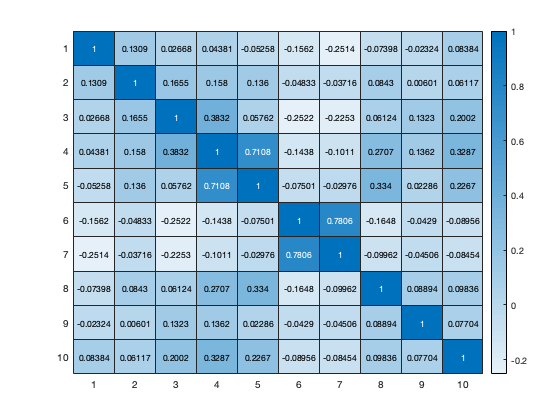

ans =   HeatmapChart with properties:

        XData: {10×1 cell}
        YData: {10×1 cell}
    ColorData: [10×10 double]

  Show all properties


heatmap(r)

The heatmap makes it very easy to pinpoint the highest and lowest correlation features.  

Another tool in MATLAB for visualizing raw data correlations is `gplotmatrix`. This command creates a matrix of scatter plots for each variable in the dataset against every other variable. 

xnames = var_names

xnames = 1×10 cell array
    {'SEX'}    {'TOTCHOL'}    {'AGE'}    {'SYSBP'}    {'DIABP'}    {'CURSMOKE'}    {'CIGPDAY'}    {'BMI'}    {'DIABETES'}    {'BPMEDS'}


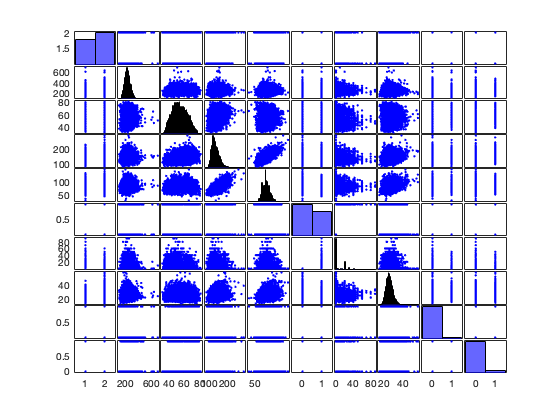

gplotmatrix(fram_noNaN.Variables)

The diagonals in the matrix show the outlines of the grouped histograms. There are a number of other options for viewing this correlation matrix. For example, we can group the results based on gender and display the variable names in the diagonal, instead of the histograms.

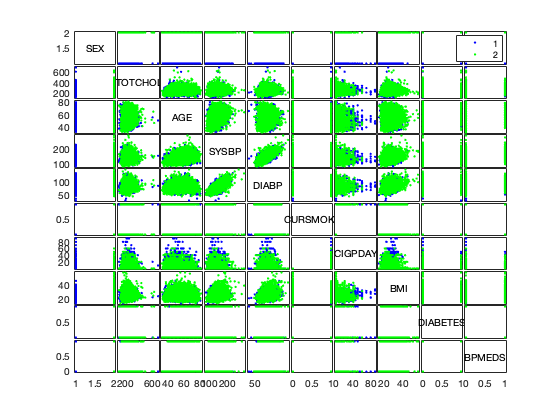

Error using clo (line 53)
Error while evaluating Figure SizeChangedFcn.



ans =   Text (BPMEDS) with properties:

                 String: 'BPMEDS'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'center'
               Position: [0.5000 0.5000 -0.1000]
                  Units: 'normalized'

  Show all properties


gplotmatrix(fram_noNaN.Variables,[],fram_noNaN.SEX,[],[],[],[],'variable',xnames)

### Regression

General steps working analyzing regression within a dataset

- Start with a hypothesis or specific goal (e.g. predicting BMI from age)

- Identify the feature you want to predict, the response variable (e.g. BMI)

- Identify the predictors - age, sex, heart rate (the input data)

- Do you expect a linear relationship?

- Visualize variables using plot functions

# Do we want to run through an example here or only in next section?

### Regression - Creating a Model

When creating a regression model, it is helpful to start with the simplest model (single variable) and then gradually increase the complexity. 

Simple linear regression is used for the two-variable models. With linear regression, we examine the explanatory variable and the response variable, and try to fit a linear equation to the data ($Y_1 =b*X$*)*. 

Can we predict BMI from total cholesterol? There are two ways to find the slope (regression coefficient) of  single-variable linear regression models*.*

1.) Use the `\` operator.

fram_noNaN.TOTCHOL \ fram_noNaN.BMI

ans = 0.1037

2.) Use the `regress `command. The `regress` command removes NaN values, so we can use the original data. Before carrying out the command, let's assign the total cholesterol arrays to variables X and Y, respectively.

X = fram.TOTCHOL;
Y = fram.BMI;
b = regress(Y,X)

b = 0.1038

These two methods produce the same results for *b*. In terms of predicting BMI from total cholesterol, we now have the equation $Y_1 =b*X$, where $Y_1$ is estimated BMI, *b *is the regression coefficient, and *X *is total cholesterol. Create an array containing the predicted BMI values using this equation.

Y1 = b*X;

To improve the regression model, we want to include an intercept term. In order to this, a column of ones must be added to independent variable matrix.

X_ones = [ones(size(X)) X];

Now repeat the `regress` command with the new X*.*

b_single = regress(Y,X_ones)

b_single =    24.1091
    0.0072


The first term in the *b *array is the y-intercept for the linear regression line, and the second term is the slope. We now have the equation $Y_1 =b_0 *X+b_1$. Use these values to create an array which contains the new values for $Y_1$. 

Y1_single = b_single(2)*X_ones(:,2)+b_single(1);

How do the two estimates for $Y_1$ compare? And how do these compare to that actual BMI data? Use the `scatter` and `plot `functions to compare.

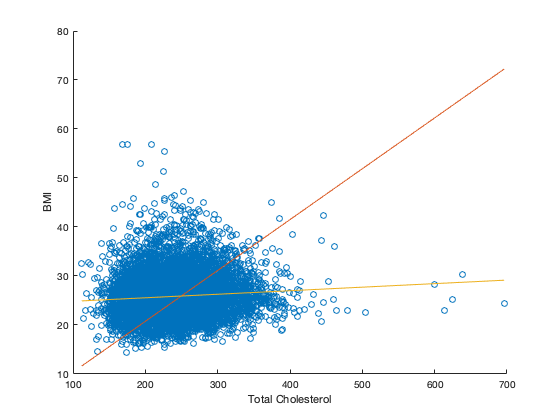

scatter(X,Y)
xlabel('Total Cholesterol')
ylabel('BMI')
hold on
plot(X,Y1)
hold on
plot(X,Y1_single)
hold off

Looking at the actual total cholesterol versus BMI data, it is difficult to see any strong linear relationship. However, the linear regression model which includes the intercept term is clearly a better fit to the data.

### Regression Model - Forecasting

We can use the regression model to predict impact in new conditions. 

Predict the BMI for a hypothetical person with a total cholesterol value of 200.

BMI_200 = b_single(2)*200 + b_single(1)

BMI_200 = 25.5538

### Regression - Predicting New Values

Using the regression coefficient, we can examine how the predicted BMI changes with total cholesterol. For example, make an array of values from the minimum to maximum cholesterol values in increments of 10.

chol_range = min(X):10:max(X);

Create an array which contains the corresponding predicted BMI values.

Y1_predict = b_single(2)*chol_range+b_single(1);

Create a scatter plot with the new $Y_1$

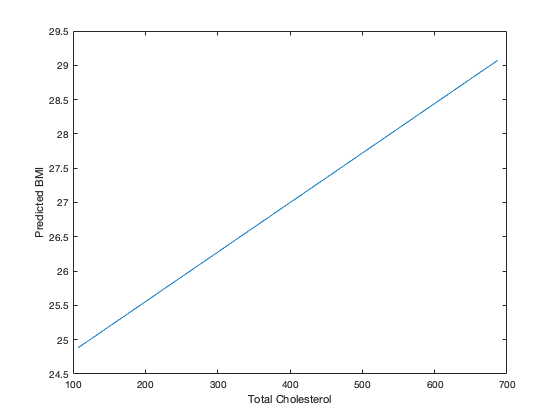

plot(chol_range,Y1_predict)
xlabel('Total Cholesterol')
ylabel('Predicted BMI')

We can also insert a best fit line on the original data set using the `lsline` function.

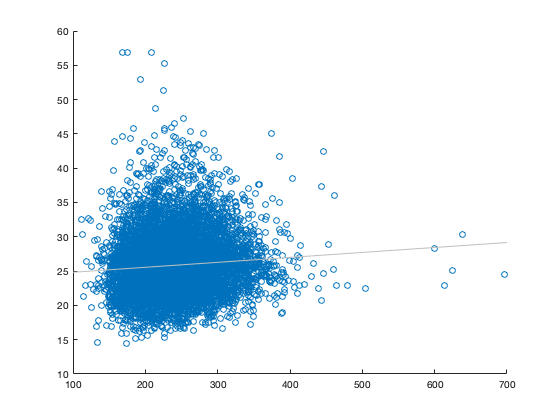

scatter(X,Y)
lsline

Another method for performing linear regression uses the `fitlm `command. The `fitlm` command outputs a linear regression model when given the predicting variable and the response variable.

fitlm(X,Y)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)       24.109       0.20852    115.62             0
    x1             0.0072236    0.00084972    8.5012    2.1157e-17


Number of observations: 11173, Error degrees of freedom: 11171
Root Mean Squared Error: 4.07
R-squared: 0.00643,  Adjusted R-Squared: 0.00634
F-statistic vs. constant model: 72.3, p-value = 2.12e-17

The intercept and regression coefficient terms from the `fitlm `function give us the same equation for the best fit line as when we used the `regress` function: $Y_{1\;} =0\ldotp 0072X+24\ldotp 1$

Create a linear model which uses age to predict BMI. Plot the data points, the best fit line and find the linear regression equation.

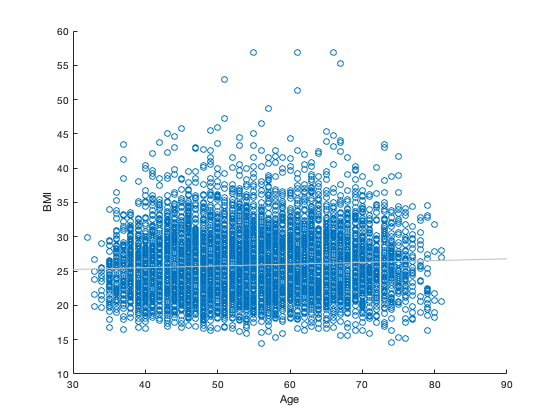

age = fram.AGE;
scatter(age,Y)
xlabel('Age')
ylabel('BMI')
lsline

fitlm(age,Y)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      24.458       0.2217    110.32             0
    x1             0.025918    0.0039875    6.4999    8.3704e-11


Number of observations: 11575, Error degrees of freedom: 11573
Root Mean Squared Error: 4.1
R-squared: 0.00364,  Adjusted R-Squared: 0.00355
F-statistic vs. constant model: 42.2, p-value = 8.37e-11

The equation for the best fit line is $\mathrm{BMI}=0\ldotp 0259*\mathrm{Age}+24\ldotp 458\ldotp \;$The positive slope indicates that BMI increases with age. However, the slope is so close to zero that we can assume that the effect of age on BMI is very minimal.

### Multi-linear Regression

Most diseases and biomedical processes involve multiple parameters. In these instances, several variables may be needed to accurately predict the response variable. 

For example, BMI may be a function of age, sex, glucose, cholesterol and heart rate. The `regress `function can still be used for multi-linear regression models. To create a linear regression model with these variables, we will make a matrix containing all of the predictors plus the column of ones.

X_multi = [ones(size(fram.AGE)) fram.AGE, fram.SEX, fram.TOTCHOL, fram.GLUCOSE, fram.HEARTRTE];
Y_multi = fram.BMI;
b_multi = regress(Y_multi,X_multi)

b_multi =    22.3565
    0.0148
   -0.7409
    0.0074
    0.0113
    0.0141


What do the outputs of the `regress` function tell us about our model? These values are the regression weights and correspond to the effect of each independent variable on the dependent variable. 

Based on the results, the patient's sex has the greatest impact on their BMI, although it is a negative correlation. Given our knowledge that male (represented by 1's) have higher BMI values than females (represented by 2's), this weight makes sense. BMI has a tendency to decrease as the value for sex increases. 

All of the other variables have positive correlations with BMI, although to a lesser effect. We would expect for BMI to increase with age, total cholesterol, glucose levels and heart rate. 

### Multi-linear Regression - Assess Accuracy

To obtain more information about the linear regression model when using the `regress` command, use the *stats* option. This option provides the R-squared statistic, F-statistic, p-value, and estimated error variance.

Find the R-squared value for the single-variable and multi-variable regression models that we made.

[b,~,~,~,stats] = regress(Y,X_ones)

b =    24.1091
    0.0072


stats =     0.0064   72.2696    0.0000   16.5300


[b_multi,~,~,~,stats] = regress(Y_multi,X_multi)

b_multi =    22.3565
    0.0148
   -0.7409
    0.0074
    0.0113
    0.0141


stats =     0.0235   48.2844    0.0000   15.9388


The R-squared value increased from 0.0064 to 0.0235 from the single-variable model to the multi-variable model. 

While both values are very low, it makes sense that the R-squared value for the multi-variable linear regression is higher as we have more predicting factors for the BMI.

### Logistic Regression 

Logistic regression is useful for discrete categorical data (in contrast to continuous data for linear regression).

Example – Classifying patients with diabetes vs normal. Recall that in the diabetes dataset, 0 indicates non-diabetic and 1 indicates diabetic.

Similar to the `regress `function, we can use the `mnrfit` to predict diabetes from multiple variables, in this case BMI, glucose and cholesterol. The `mnrfit` command returns a matrix of coefficient estimates for a multinomial logistic regression of the response variable based on the predictor variables. 

Note that the response variable must be discrete, but the predictors can be continuous.

diabetes = categorical(fram.DIABETES);
predictors = [fram.BMI, fram.GLUCOSE, fram.TOTCHOL];
[B,~,stats] = mnrfit(predictors,diabetes);
B

B =    10.6017
   -0.0670
   -0.0567
   -0.0009


The first value in *B *contains the intercept term for the relative risk of the first category, non-diabetic, versus the second category, diabetic. The remaining rows contain the slopes for the model of the non-diabetic group. The `mnrfit` function uses the last category (diabetic) as the reference category. 

In addition to describing the effects of the predictor variables on the response variable, the coefficients provide information about the relative risk of being in one category versus another. For example, the coefficient -0.067 indicates that the relative risk of being non-diabetic versus diabetic decreases exp(0.067) for every each unit increase in BMI if all else is equal.

We can also check if each model coefficient is statistically significant.

stats.p

ans =     0.0000
    0.0000
    0.0000
    0.4599


We typically look for a p-value below 0.05 for determining whether the hypothesis is significant or not. The last p-value, which corresponds to total cholesterol, is much greater than 0.05, indicating that this coefficient is not significant to the model. 

# Should we perform mnrfit on individual predictors as well?

### Logistic Regression - Forecasting for New Datasets

We can use the `mnrval` function to evaluate the response variable (i.e. Diabetes) for new values of predictor variables. The inputs for `mnrval` include the coefficient estimates we created with the `mnrfit `function and the values for the predictor variables that we want to analyze. The output of the function indicates the probability of belonging to each response category (Diabetic vs Non-Diabetic). 

Example: Predict if a person with BMI = 30, Glucose =88, and Cholesterol = 255 has diabetes.

x = [30 88 255];
prob = mnrval(B,x);
prob

prob =     0.9666    0.0334


Based on these results, a person with these BMI, cholesterol and glucose levels has a 3.34% chance of having diabetes. Keep in mind that only 530 of the 11627 patients in the dataset (4.56%) are diabetic.

Use the same method to predict whether a patient suffered a stroke during the study (1) or not (0) based on their age, systolic blood pressure and cigarettes smoked per day. We will look at two different patients with the following characteristics: 

- **Patient 1:** Age = 50, Systolic Blood Pressure = 135, Cigarettes Smoked per Day = 6

- **Patient 2:** Age = 30, Systolic Blood Pressure = 130, Cigarettes Smoked per Day = 0

stroke = categorical(fram.STROKE);
predictors = [fram.AGE,fram.SYSBP,fram.CIGPDAY];
[B,~,stats] = mnrfit(predictors,stroke);
B

B =     8.3484
   -0.0548
   -0.0197
   -0.0125


x1 = [50,135,6];
prob_stroke_1 = mnrval(B,x1)

prob_stroke_1 =     0.9464    0.0536


x2 = [30,130,0];
prob_stroke_2 = mnrval(B,x2)

prob_stroke_2 =     0.9843    0.0157


As we might expect, Patient 2 has a lower probability (1.57% vs. 5.36%) of having suffered a stroke due to their lower age, blood pressure and cigarette-use. 

### Visualizing the Fit

The `gscatter` function creates a scatter plot grouped by category. Two vectors of the same size are needed as arguments (in this case two predictors such as BMI and glucose). A grouping variable must be in the form of a categorical variable (in this case diabetes).

Use `gscatter` to plot glucose versus BMI, grouped by diabetes.

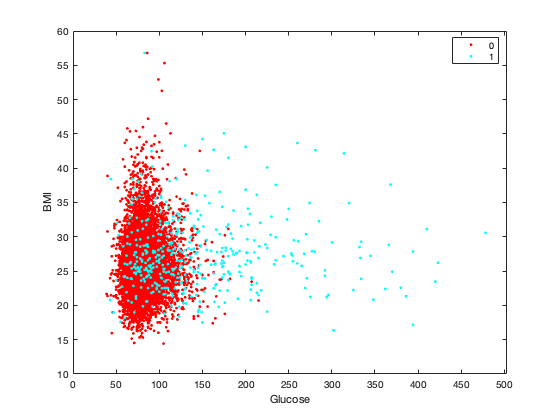

gscatter(fram.GLUCOSE, fram.BMI, fram.DIABETES)
xlabel('Glucose')
ylabel('BMI')

In this example, `gscatter` makes it easy to see that essentially all of the data points at high glucose levels belong to patients with diabetes.

Repeat this process with systolic blood pressure versus total cholesterol, grouped by cardiovascular disease.

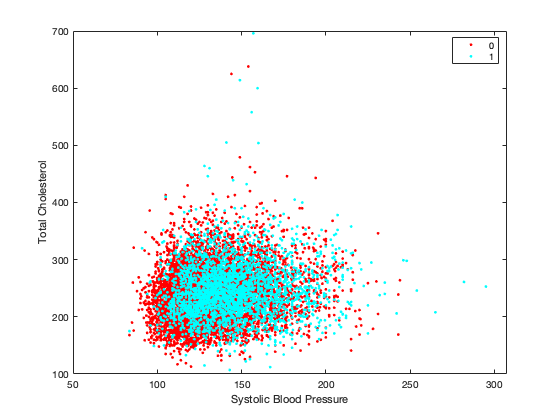

gscatter(fram.SYSBP,fram.TOTCHOL,fram.CVD)
xlabel('Systolic Blood Pressure')
ylabel('Total Cholesterol')

Unlike the last example, there aren't any apparents trends between the data groups. Upon close inspection, it appears that a slight majority of patients with higher heart rates also suffered from CVD. In some cases, we may want to use this tool to help confirm that the data points are equally distributed throughout the different categories.

### Polynomial Regression

The `polyfit `function is similar to `regress`, however it is more general in that `polyfit `can be used for linear, quadratic or polynomial models. The function returns the coefficients in descending powers and their length is *n+1. *

Create a first order model for systolic and diastolic blood pressure.

p = polyfit(fram.SYSBP,fram.DIABP,1)

p =     0.3640   33.4209


These coefficients represent the following best fit equation: $p\left(x\right)=0\ldotp 364x+33\ldotp 42$

We can use the `polyval `function to plot the calculate the polynomial's value, *p*, at each point, *x*. Plot the original blood pressure data and the first-order best fit line on the same graph.

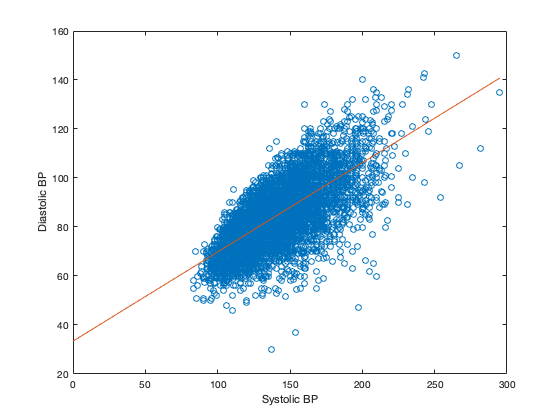

x1 = linspace(0,max(fram.SYSBP));
y1 = polyval(p,x1);
figure
plot(fram.SYSBP,fram.DIABP,'o')
xlabel('Systolic BP')
ylabel('Diastolic BP')
hold on
plot(x1,y1)
hold on

Use `polyfit` once again, this time to create a quadratic model of the systolic and diastolic blood pressure relationship.

p2 = polyfit(fram.SYSBP,fram.DIABP,2)

p2 =    -0.0013    0.7439    6.3051


These coefficients form the following quadratic equation: $p\left(x\right)=-0\ldotp 0013x^{2\;} +0\ldotp 7439x+6\ldotp 305$

Add this best fit line to the previous plot.

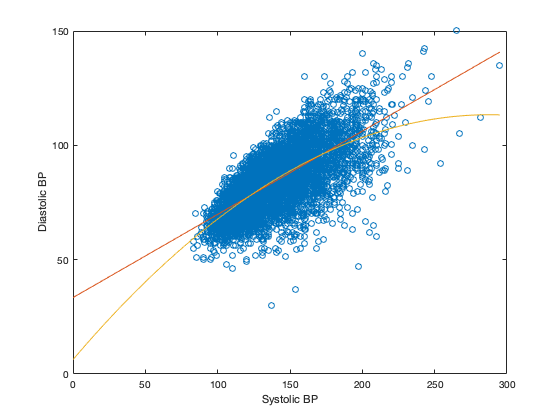

y2 = polyval(p2,x1);
plot(x1,y2)
hold off

In regression analysis, it is important to keep the order of the model as low as possible. In this example, it appears that the first-order model actually fits the data better. The use of polynomials of higher orders can lead to incorrect evaluations. 